# Clear workspace before run

clear all;
close all;

## USER INPUT: Path to file to load

grid_data_path = 'test_data/occupancy_grid_recording.mat';
scans_to_plot = []; % set to empty to plot all scans

## Load grid file and convert to correct format

load(grid_data_path);
% consider using function matfile, because it is faster
% matfile(grid_data_path, 'Writable',false);
grid_map = Utilities.loadGridMap(grid_data); % Uncompress the mat_file data

% Create scans to scans_to_plot
if(isempty(scans_to_plot))
    scans_to_plot = 1:scan_number;
else
    scans_to_plot(scans_to_plot>scan_number) = [];
    scans_to_plot(scans_to_plot<1) = [];
end

## Initialize Grid Plotter

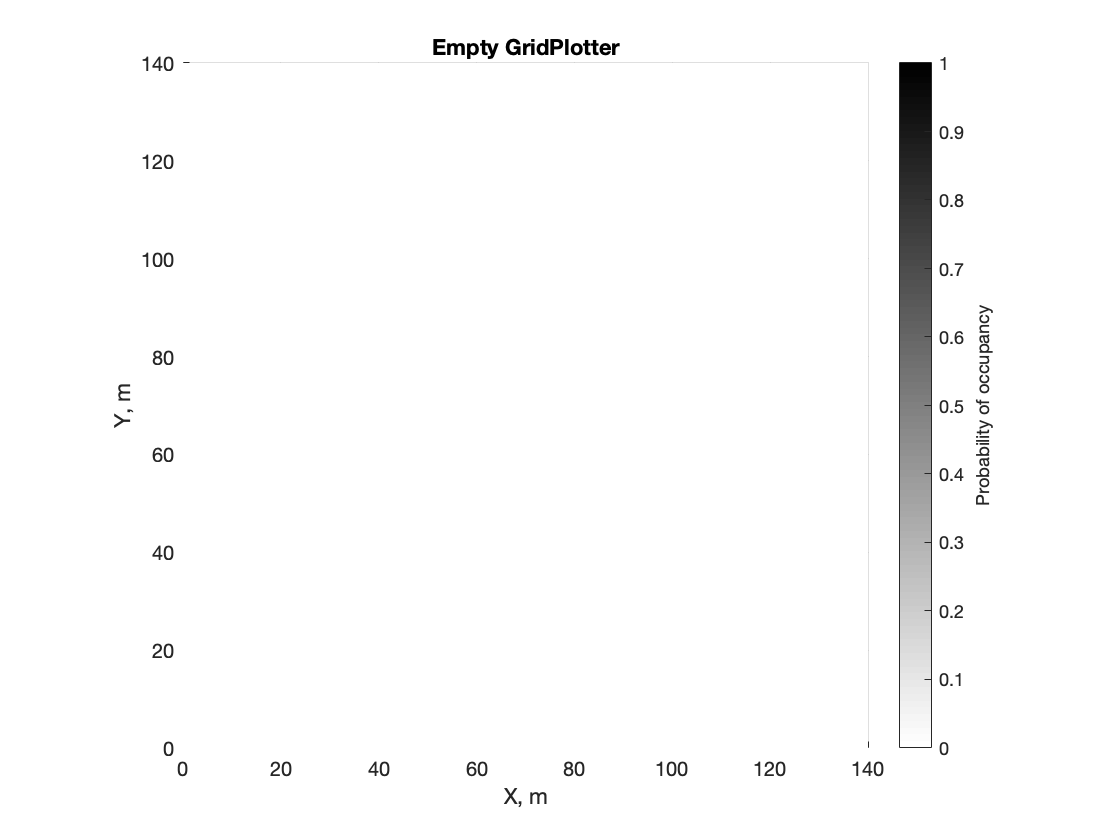

fig = figure();
AX = axes(fig);
Plotting.initializePlotter(AX, grid_size);
grid_plotter = Plotting.GridPlotter(AX, grid_size, grid_resolution);
host_plotter = Plotting.HostPlotter(AX);

## Run Plotter

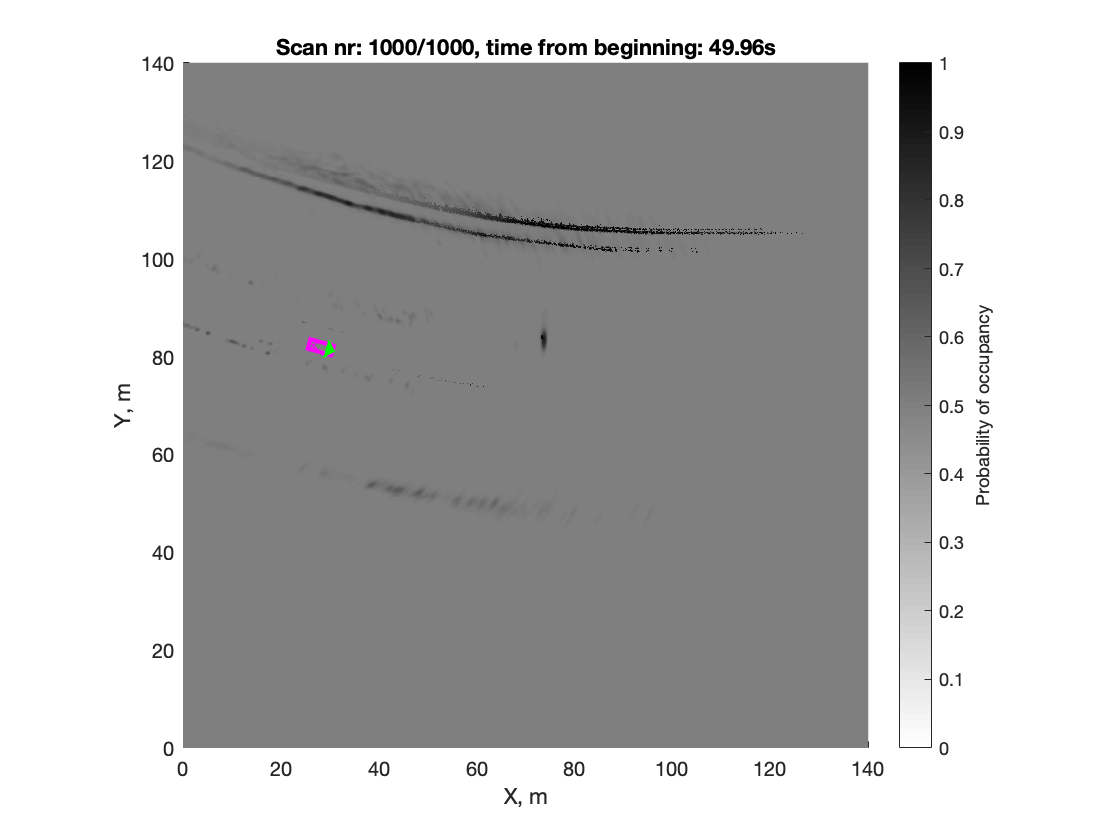

for scan_idx = scans_to_plot
    grid_plotter.updateGrid(grid_map{scan_idx}, ...
        sprintf("Scan nr: %d/%d, time from beginning: %2.2fs", scan_idx, scan_number, host_pose{scan_idx}.ts));
    host_plotter.updateHostPose(host_pose{scan_idx});
    pause(0.01); % required to force figure update
end